**Priprema okruženja**

clear variables
close all
clc

**Učitavanje podataka o sistemu**

load("System data.mat","System") ; 

**Definisanje broja promjenljivih i njihovih graničnih vrijednosti**

Number_of_Variables = 3 ;
Lower_Bounds = [0.9 0.9 0] ;
Upper_Bounds = [1.1 1.1 2] ;

**Definisanje opcija za optimizacioni algoritam**

Options = optimoptions('ga') ;
Options.PopulationSize = 30 ; 
Options.ConstraintTolerance = 1e-6 ;
Options.FunctionTolerance = 1e-6 ; 
Options.Display = 'iter' ;
Options.PlotFcn = 'gaplotbestf' ; 
Options.UseParallel = true ; 

**Poziv optimizacionog algoritma**


Single objective optimization:
3 Variable(s)
19 Nonlinear inequality constraint(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 4).

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1           1515   5.03387e+06    3.338e-09      0
    2           2995   5.03386e+06    6.025e-09      0
    3           4470   5.03386e+06    7.003e-09      0
Optimization terminated: average change in the fitness value less than options.FunctionTolerance
 and constraint violation is less than options.ConstraintTolerance.


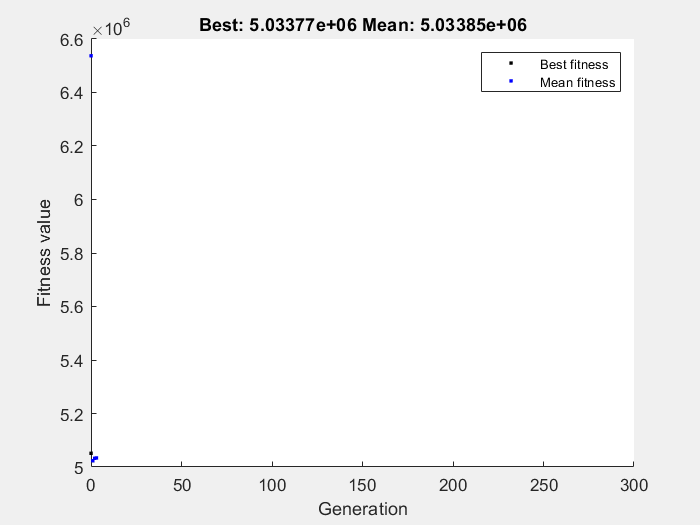

tic
[x,fval,exitflag,~] = runobjconstr(Lower_Bounds,Upper_Bounds,System,Options) ;

toc

Elapsed time is 91.080426 seconds.
